## Spectral Differentiation

In this livescript is you will learn

- How to use spectral differentiation to approximate derivatives

- When spectral differentiation doesn't work

#### Spectral Differentiation

The main idea behind spectral differentiation is to base the derivative on the Lagrange interpolant rather than the Taylor series of $f$.

To see what this looks like, we'll consider the function


$$f(x)=\sin{(x)}\exp{(x^{2})}$$


which looks like

x = linspace(-1,1,1000);
f = @(x) sin(x).*exp(x.^2);

plot(x,f(x))
hold on

and has the derivative 


$$f'(x)=\exp{(x^{2})}\cos{(x)}+2\exp{(x^{2})x\sin{(x)}$$


To approximate the funciton with a Lagrange polynomial, we're free to choose the interpolation points, and for simplicity, we'll choose evenly spaced points.

Then for 4 points, the interpolating polynomial can be found by using $\texttt{polyfit()$ and $\texttt{polyval()}$

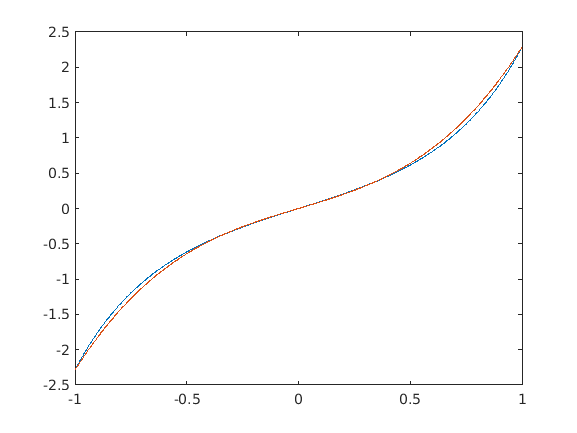

N = 3;
xp = linspace(-1,1,N+1);
f_n = polyfit(xp,f(xp),N);
f_interp = polyval(f_n,x);

plot(x,f_interp)
hold off

The derivative may then be approximated by differentiating the interpolating polynomial using $\texttt{polyder()}$

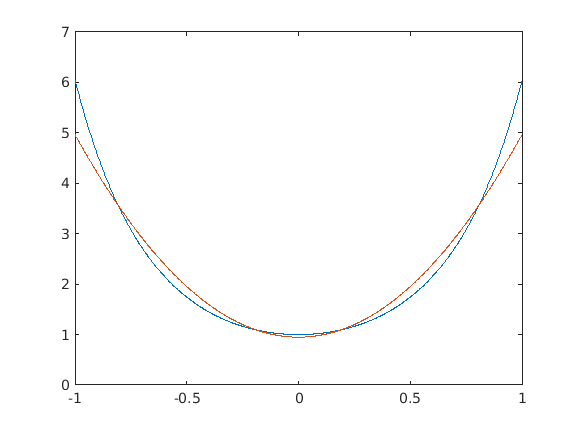

f_dash = @(x) exp(x.^2).*cos(x)+2*exp(x.^2).*x.*sin(x);
f_dash_interp = polyval(polyder(f_n),x);

plot(x,f_dash(x))
hold on
plot(x,f_dash_interp)
hold off

We can see that the derivative is quite well approximated using the derivative of the interpolating polynomial. And in fact, this will hold whenever the interpolant approximates the function well.

However, getting MATLAB to approximate the function and take derivatives defeats the purpose of this course, so we'll look into how this is done.

If we write our approximation in terms of a Lagrange polynomial, we have


$$f_{n}(x)=\sum^{N}_{i=0}{f_{i}L_{i}(x)$$


where we have $f_{i}\equiv f(x_{i})$. Then the derivative may be written as


$$f'_{n}(x)=\sum^{N}_{i=0}{f_{j}L'_{j}(x)$$


which in terms of a matrix multiplcation is


$$f'_{N}(x)
=

\pmatrix{
L'_{0}(x) & 
\cdots & 
L'_{N}(x)
}
\pmatrix{
f_{0}\cr
\vdots\cr
f_{N}
}$$


Often we're interested in the values of the derivatives at the interpolation nodes, for instance, two-point boundary value problems, so we form a vector of $f_{N}(x_{j})$'s to give 


$$\pmatrix{
f'_{N}(x_{0})\cr
\vdots\cr
f'_{N}(x_{N})\cr
}
=

\pmatrix{
L'_{0}(x_{0}) & \cdots & L'_{N}(x_{0})\cr
\vdots & \ddots & \vdots \cr
L'_{0}(x_{N}) & \cdots & L'_{N}(x_{N})
}
\pmatrix{
f_{0}\cr
\vdots\cr
f_{N}
}$$


So the differential operator at each of the nodes is given by the very creatively named derivative matrix 


$$[D]
=
\pmatrix{
L'_{0}(x_{0}) & \cdots & L'_{N}(x_{0})\cr
\vdots & \ddots & \vdots \cr
L'_{0}(x_{N}) & \cdots & L'_{N}(x_{N})
}$$


Although not conceptually difficult, the derivatives of the Lagrange basis polynomials at nodes can tediously be derived to give


$$D_{ij}\equiv\frac{dL_{j}}{dx}(x_{i})
=
\cases{\frac{(x_{i}-x_{0})\cdots(x_{i}-x_{i-1})(x_{i}-x_{i+1})\cdots(x_{i}-x_{N})}{(x_{i}-x_{j})(x_{j}-x_{0})\cdots(x_{j}-x_{j-1})(x_{j}-x_{j+1})\cdots(x_{j}-x_{N})} & $i \neq j$ \cr
\frac{1}{x_{i}-x_{0}}+\cdots+\frac{1}{x_{i}-x_{i-1}} +\frac{1}{x_{i}-x_{i+1}}+\cdots+\frac{1}{x_{i}-x_{n}}& $i=j$
}$$


Notice how the matrix $[D]$ is full, which means that the derivative at a point $x_{k}$ depends on the values in the entire domain. As such, we call these methods *global*, compared with a finite difference method, which is a* local method* as the derivative only depends on values nearby.

The code to condtruct the derivative matrix is quite simple if we consider the component parts.

We'll begin with the case $i\neq j$ and consider the third Lagrange basis function $L_{2}'$ at the second point $x_{1}$. Remember, our indexing starts at 0.

N = 3;
xp = linspace(-1,1,N+1);
i = 2;
j = 3;

Then we may split up the fraction into 


$$\frac{\texttt{num}}{\texttt{(x\_i-x\_j)denom}}$$


where $\texttt{num}$ is given by the product of $(x-x_{k})$ for $k\neq i$

num = 1;
for k=1:N+1
    if k~=i
        num = num*(xp(i)-xp(k));
    end
end
num

num = 0.5926

and $\texttt{denom}$ is the product of $(x_{j}-x_{k})$ for $k\neq j$

denom = 1;
for k=1:N+1
    if k~=j
        denom = denom*(xp(j)-xp(k));
    end
end
denom

denom = -0.5926

Then the derivative of the Lagrange basis polynomial is given by

L_dash = num/((xp(i)-xp(j))*denom)

L_dash = 1.5000

In the case when $i=j$, we're just summing up the fractions 


$$\frac{1}{x_{i}-x_{k}}$$


for $k\neq i$.

Thus, the code to do this for $D_{11}$ is given by

i = 2;
j = 2;

D = 0;
for k=1:N+1
    if k~=i
        D = D+(1/(xp(i)-xp(k)));   
    end
end
D

D = -0.7500

Wrapping the code in additional for loops to loop through the entire matrix $[D]$, we have

Hence, the derivative at the interpolation nodes is given by

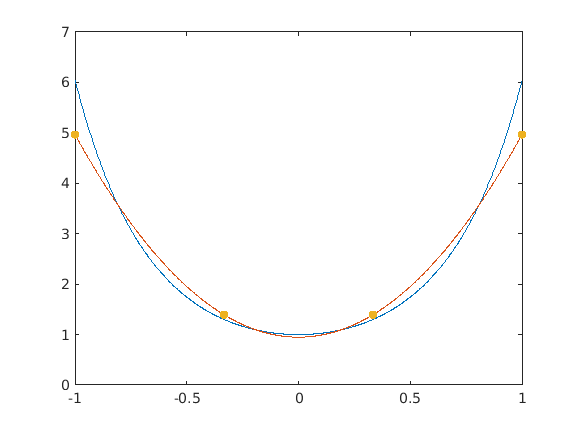

N = 3;
xp = linspace(-1,1,N+1);

D = DerivMatrix(xp,N);
f_dash_matrix = D*f(xp)';

plot(x,f_dash(x))
hold on
plot(x,f_dash_interp)
plot(xp,f_dash_matrix,'.','MarkerSize',15)
hold off

which is the same as what we found before.

However, as we've seen previously, evenly spaced nodes can result in large oscillations in the interpolant, so it usually better to use Gauss-Legendre or Gauss-Lobatto nodes. 

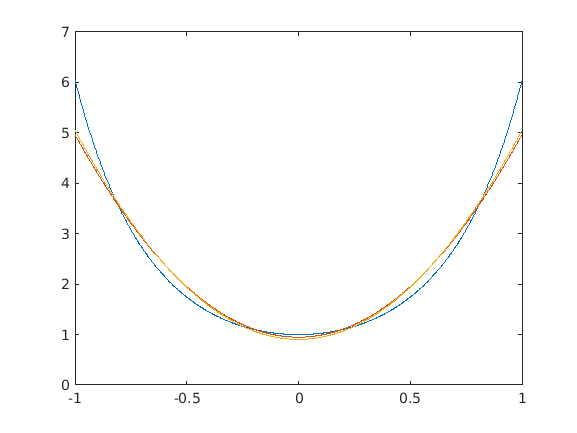

xpGL = GLL_nodes(N);
D = DerivMatrix(xpGL,N);
f_dash_matrix_GL = D*f(xpGL);

plot(x,f_dash(x))
hold on
plot(x,polyval(polyfit(xp,f_dash_matrix,N-1),x))
plot(x,polyval(polyfit(xpGL,f_dash_matrix_GL,N-1),x))
hold off

(a)    Rerun the previous code with higer order interpolating polynomials

#### Limitations of Spectral Differentiation

Consider the function 


$$f(x)=\max{\{0,1-2|x|\}}$$


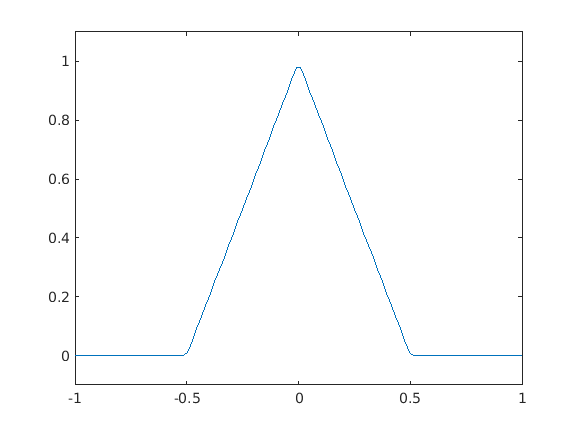

x = linspace(-1,1,100);
f = @(x) max(0,1-2*abs(x));

plot(x,f(x))
ylim([-0.1,1.1])

which has also very cleverly been called a hat function because it looks like a hat. Although personally, a Runge function looks like it'd make a better hat.

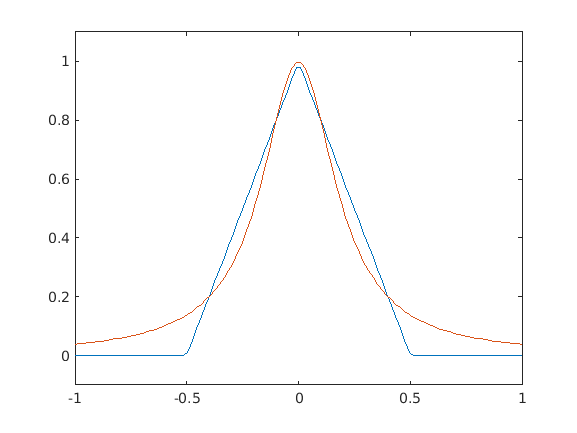

hold on
plot(x,1./(1+25*x.^2))
hold off

(b)     Show that the derivative is given by


$$f'(x)
=
\begin{cases}
0 & x<-\frac{1}{2}\\
2 & -\frac{1}{2}\leq x<0 \\
-2 & 0\leq x <\frac{1}{2}\\
0 & \geq \frac{1}{2}
\end{cases}$$


To aproximate the derivative, we'll use 20 Gauss-Legendre-Lobatto nodes

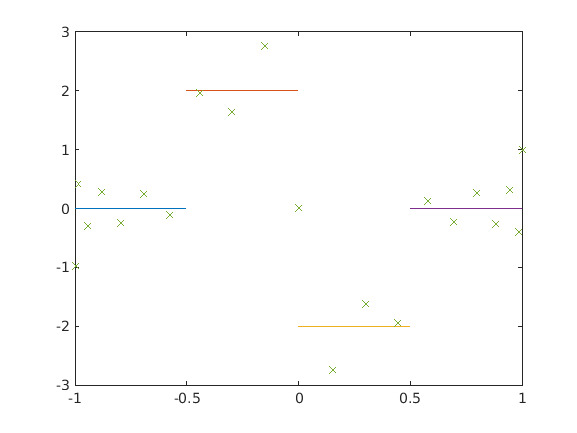

N = 20;
xp = GLL_nodes(N);
fp = f(xp);
D = DerivMatrix(xp,N);
f_dash = D*fp;
f_dash_interp = polyval(polyfit(xp,f_dash,N-1),x);

plot([-1,-0.5],[0,0],[-0.5,0],[2,2],[0,0.5],[-2,-2],[0.5,1],[0,0])
hold on
plot(xp,f_dash,'x')
hold off

What we can see here is that using spectral differentiation gives a very poor approximation of the derivative.

The reason behind this is that while $f$ is continuous, its derivatives aren't. So it's very difficult to approximate $f$ using a Lagrange polynomial. 

Looking at the interpolating polynomial

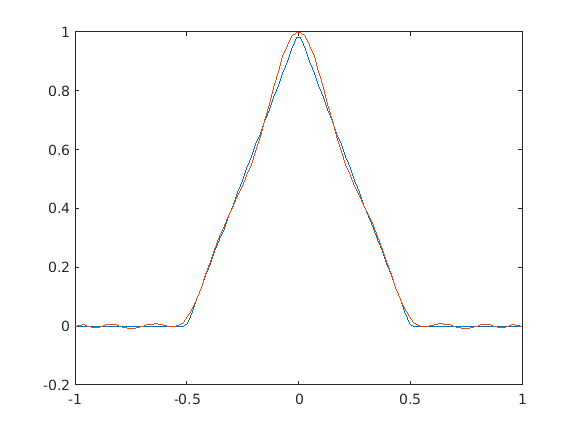

f_approx = polyval(polyfit(xp,f(xp),N),x);

plot(x,f(x))
hold on
plot(x,f_approx)
hold off

we can see that there are quite a few wiggles in $f$, which results in the oscillations in the derivative.

function D=DerivMatrix(x,n)
    D=zeros(n+1,n+1);
    for i=1:n+1    
        num(i)=1.0;    
        for k=1:n+1        
            if k ~= i            
                num(i)=num(i)*(x(i)-x(k));        
            end    
        end
    end
    for j=1:n+1    
        den(j)=1.0;    
        for k=1:n+1        
            if k ~= j            
                den(j)=den(j)*(x(j)-x(k));        
            end    
        end
    end
    for i=1:n+1    
        for j=1:n+1        
            if i ~= j            
                D(i,j)=num(i)/(den(j)*(x(i)-x(j)));        
            end    
        end
    end
    for i=1:n+1    
        for k=1:n+1        
            if i~=k            
                D(i,i)=D(i,i)+1./(x(i)-x(k));        
            end    
        end
    end
end   


function yint=LagrangePolynomial(x,y,n,xint)
    yint=zeros(size(xint));
    for i=1:n+1    
        Lix=1.0;    
        for j=1:n+1        
            if j ~= i        
                Lix=Lix.*(xint-x(j))/(x(i)-x(j));        
            end    
        end    
        yint=yint+y(i).*Lix;
    end
end

function xp = GLL_nodes(N)
    
    syms x
    Lo = (1-x^2)*diff(legendreP(N,x),x);
    xp = double(vpasolve(Lo == 0));
    
end